# Experimental methods in psychological sciences

Course for ENS-PSL cognitive science masters program

Part 2: Psychophysics and signal detection theory

This section is written by Tarryn Balsdon

## Section 4. Methods of manipulation

A core principle of experimental design is to measure the 'output' while varying one 'input' variable, and keeping all else the same. This way we can attribute any change in the output to that variable of input. In psychological science we know there are complex processes occuring in between input and output. These complex processes occur in a 'black box' which we cannot directly access. If we want to make inferences about the mechanisms employed in this black box, we need to go beyond measuring the relationship between input and output, to try to manipulate the mechanisms themselves. This means measuring the change in the relationship between input and output, after 'causing' some change in the mechanism or processing of the black box.

### a. Adaptation

Sensory adaptation was traditionally hailed as the 'psychophysicist's microelectrode' (Frisby, 1979) because it enables inferences about the underlying properties of neurons coding particular aspects of perception. The principle is quite simple: (relatively) prolonged exposure to a particular stimulus, changes the neural response to that stimulus, resulting in a change in our perception of that stimulus. This occurs from very low to very high levels of processing. If you look at a bright light, you then see a dark spot in the same retinal location, when you look away. This occurs at the level of the retina. If you look at a pattern of downward motion (such as a waterfall) you will then have the impression that an otherwise static texture is moving upwards. This likely occurs at a relatively low-level of processing in visual cortex, area V5/MT (Kohn & Movshon, 2003). The effect was popularised as the 'waterfall illusion'  by Addams in 1834, who wrote:

“Having steadfastly looked for a few seconds at a particular part of the cascade, admiring the confluence and decussation of the currents forming the liquid drapery of waters, and then suddenly directed my eyes to the left to observe the vertical face of the sombre age-worn rocks immediately contiguous to the waterfall, I saw the rocky face as if in motion upwards, and with an apparent velocity equal to that of the descending water.”

A simple way of understanding sensory adaptation is through the idea of response fatigue: neurons firing in response to a particular stimulus property become tired, reducing their responsiveness. The mechanisms of sensory adaptation can be far more complex (e.g. Solomon & Kohn, 2014), where sensory adaptation has been proposed to be the result of optimal resource allocation (Gepshtein, Lesmes, & Albright, 2013), which could occur for neural processes beyond perception.

Examples from high-level perception are particularly striking. In perceiving the direction of another's gaze, adaptation occurs through exposure to a particular gaze direction in faces of different identities and sizes (Clifford & Palmer, 2018). In this case, the external stimulus itself changes dramatically, with only the property of gaze direction held constant.

The coolest thing about adaptation is that we can measure properties of neurons from behaviour alone. Here we will simulate an example of orientation adaptation, with the principle of fatigue, but note that things can get far more complex than this.

V1, the first cortical step of visual processing, contains neurons whose firing rates are a function of orientation. Specifically, we can model firing rate as modulated according to a circular gaussian (Von Mises) distribution, with a certain mean and concentration (~ inverse variance). Here, we will simulate the responses of a few V1 neurons, pre- and post-adaptation, and output the associated perceived orientation based on the neural response.

NOTE: There is a lot of math in the below that is entirely tangential to this course. I've left it in in case someone is interested, but the main point can be gleaned from the figures alone.

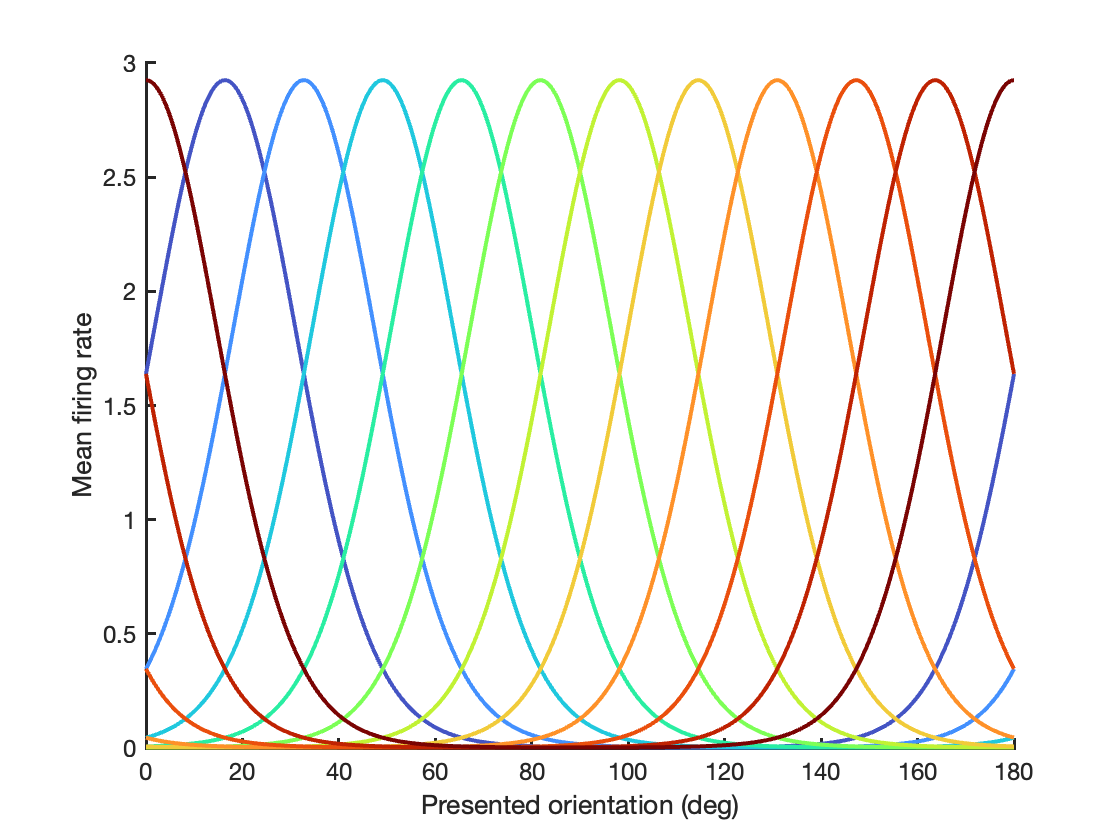

% let's pretend V1 has 12 neurons, whose firing rates are tuned according
% to distributions with means equidistant across the full 180 degrees
% of possible orientations.

nneurons = 12;
v1mus = linspace(0,pi,nneurons)';
kappa = 3.65; % estimating fwhm of about 70 deg, similar to real neurons

% von mises distribution for 0-180 degrees
vmdist = @(x,kappa,mu) (1/(pi*besseli(0,kappa))).*exp(kappa*cos(2*(x-mu)))*2;
% multiplying by 2 at the end there is just to increase the peak firing rate a
% bit (decreases variability in neural response)

% even sampling of orientation space, for visualisation
oris = linspace(0,pi,1800);

% firing rate functions
v1fr = vmdist(oris,kappa,v1mus); % each row is a neuron

% plot
figure;
hold on
colours = turbo(nneurons);
for ni = 1:nneurons
    plot(oris*180/pi,v1fr(ni,:),'Color',colours(ni,:),'LineWidth',2)
end
xlabel('Presented orientation (deg)')
ylabel('Mean firing rate')
makeMyPlotPretty

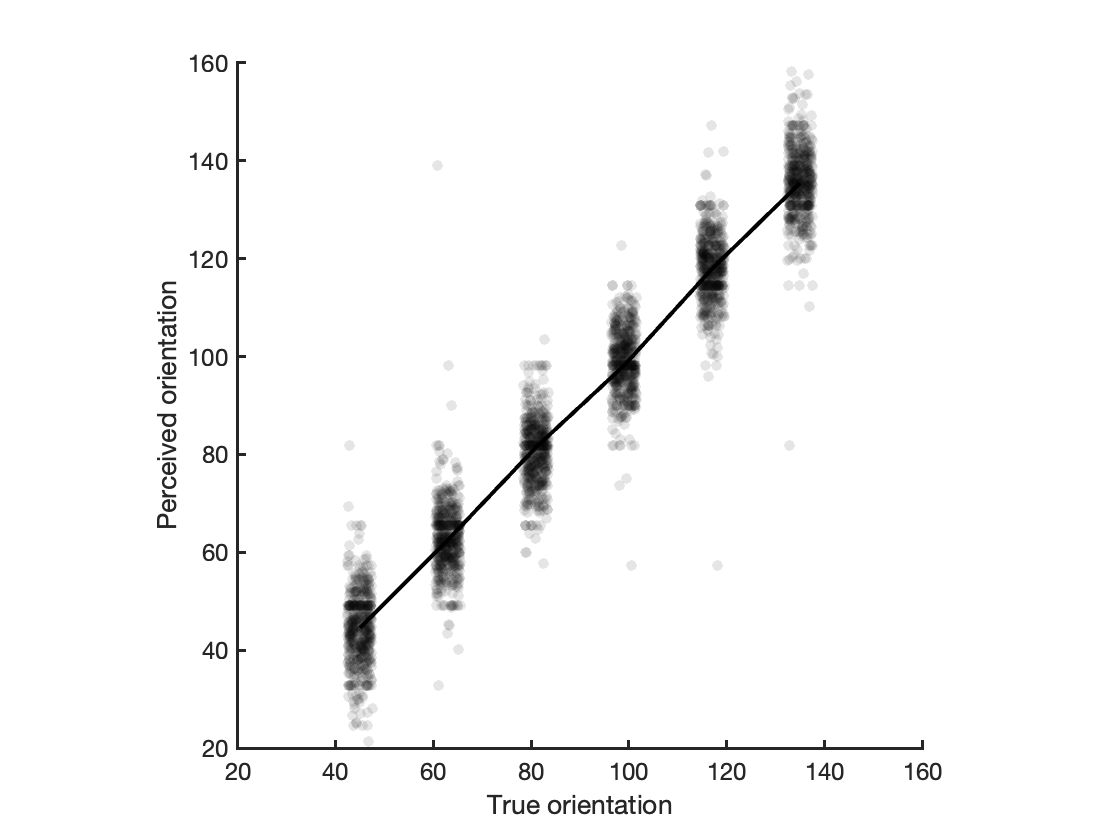

% neuron spike counts tend to be poisson distributed, the plot shows the
% mean firing rate (in response to each presented orientation), the mean 
% is also proportional to the variance (because it's a poisson)

% the log-likelihood of the stimulus orientation given the neuron's spike 
% count can be estimated as the spike count multiplied by the log of the
% firing rate function (Seung & Sompolinsky, 1993; Jazayeri & Movshon,
% 2006).

% the log-likelihood of the presented 
% orientation given the response of all neurons is the
% sum of the log likelihoods across all neurons

% the estimate of the orientation will be the maximum a posteriori 
% likelihood (MAP).

% simulate the response to a few orientations around vertical
ntest = 6;
test_oris = linspace(pi/4,3*pi/4,ntest);

nsim = 500;
map = zeros(nsim,ntest);
for ti = 1:ntest
    post = zeros(nsim,1800);
    for ni = 1:nneurons
        post = post + (poissrnd(vmdist(test_oris(ti),kappa,v1mus(ni)),nsim,1)...
            .*log(v1fr(ni,:)));
    end
    % find the maximum a posteriori
    [~,m] = max(post,[],2);
    map(:,ti) = oris(m);
end

% scatter
% with some jitter
jitter = (rand(nsim,ntest)-0.5)*5;
figure;
hold on
scatter((test_oris*180/pi)+jitter,map*180/pi,30,'k','filled','MarkerFaceAlpha',0.1)
plot(test_oris*180/pi,median(map*180/pi,1),'k','LineWidth',2)
axis([20,160,20,160])
axis square
xlabel('True orientation')
ylabel('Perceived orientation')
makeMyPlotPretty

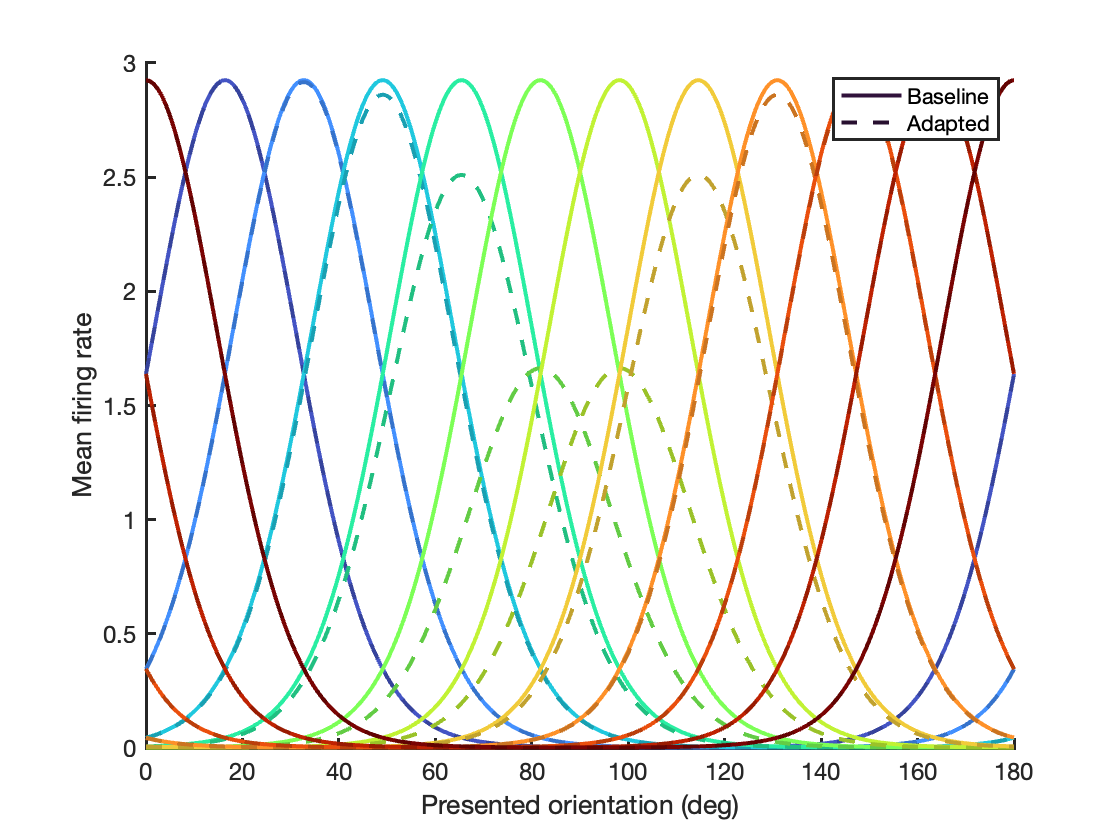

% To simulate orientation, we assume the firing rate decreases
% The amount of decrease is a function of the firing rate to the adapor
% stimulus and the strength of adaptation
% the strength of adaptation is a parameter, we call it alpha
alpha = 0.5;

% adaptor orientation
adapt = pi/2; % adapt to vertical

% now all the neurons are adapted according to their response
% proportional to their maximum firing rate
v1fr_adaptor = vmdist(adapt,kappa,v1mus)./max(max(v1fr));

% the new response:
v1fr_adapted = (1-(alpha.*v1fr_adaptor)).*v1fr;

% plot
figure;
hold on
for ni = 1:nneurons
    plot(oris*180/pi,v1fr(ni,:),'Color',colours(ni,:),'LineWidth',2)
    plot(oris*180/pi,v1fr_adapted(ni,:),'Color',colours(ni,:)*0.8,...
        'LineStyle','--','LineWidth',2)
end
xlabel('Presented orientation (deg)')
ylabel('Mean firing rate')
legend('Baseline','Adapted')
makeMyPlotPretty

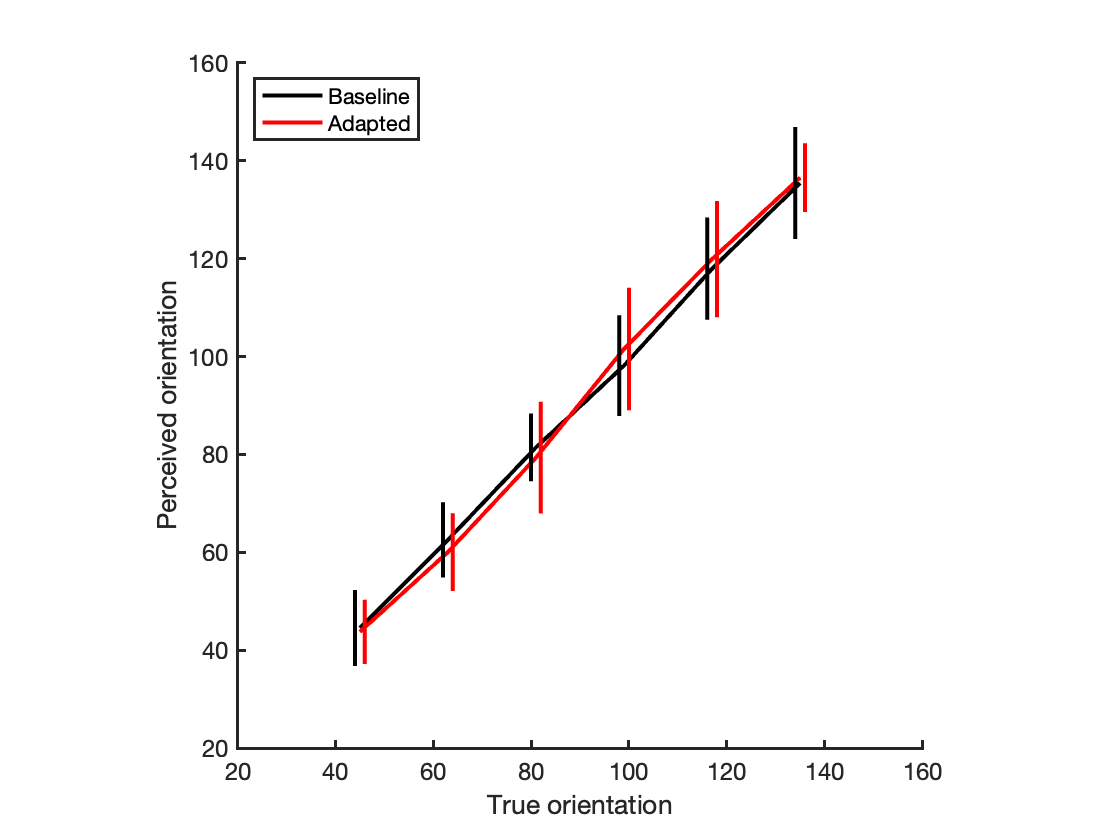


% simulate the perceived orientation post-adaptation
mapA = zeros(nsim,ntest);
for ti = 1:ntest
    post = zeros(nsim,1800);
    for ni = 1:nneurons
        post = post + (poissrnd(vmdist(test_oris(ti),kappa,v1mus(ni))...
            *(1-(alpha.*v1fr_adaptor(ni))),nsim,1).*log(v1fr_adapted(ni,:)));
    end
    % find the maximum a posteriori
    [~,m] = max(post,[],2);
    mapA(:,ti) = oris(m);
end

% plot
figure;
hold on
plot(test_oris*180/pi,median(map*180/pi,1),'k','LineWidth',2)
plot(test_oris*180/pi,median(mapA*180/pi,1),'r','LineWidth',2)
for ori = 1:ntest
    plot(([test_oris(ori),test_oris(ori)]*180/pi)-1,...
        [median(map(:,ori))+std(map(:,ori)),median(map(:,ori))-std(map(:,ori))]*180/pi,...
        'k','LineWidth',2)
    plot(([test_oris(ori),test_oris(ori)]*180/pi)+1,...
        [median(mapA(:,ori))+std(mapA(:,ori)),median(mapA(:,ori))-std(mapA(:,ori))]*180/pi,...
        'r','LineWidth',2)
end
axis([20,160,20,160])
axis square
legend('Baseline','Adapted','location','northwest')
xlabel('True orientation')
ylabel('Perceived orientation')
makeMyPlotPretty

Orientations close to the adapted orentation are perceived as repelled away from that orientation. Somewhat counterintuitively, this means that following adaptation to a vertical orientation, we would see increased sensitivity in a left/right (from vertical) orientation discrimination task. That this occurs, though we have reduced firing to orientations close to vertical gives you a sense of why this kind of adaptation can be thought of as optimal resources allocation. (Although, you might notice a slight increase in the variability of responses close to vertical).

In this example, we started with a theory of V1 neural response functions. But how do we use adaptation to make new inferences about neural responses?

For this, we might start with some simplified models. Adaptation to gaze direction is a good example for this. Neurons in the Superior Temporal Sulcus of macaque monkeys are sensitive gaze direction (Perrett et al., 1985), but it was unclear how similar neurons in human cortex may functionally encode gaze (we're mostly not allowed to stick electrodes in human brains). Palmer and Clifford (2017) tested this by comparing models of adaptation with changes in perceived gaze following adaptation in humans. A key question was whether there was a special tuning for direct gaze (where direct gaze has been proposed to be of special social importance, Senju & Johnson, 2009).

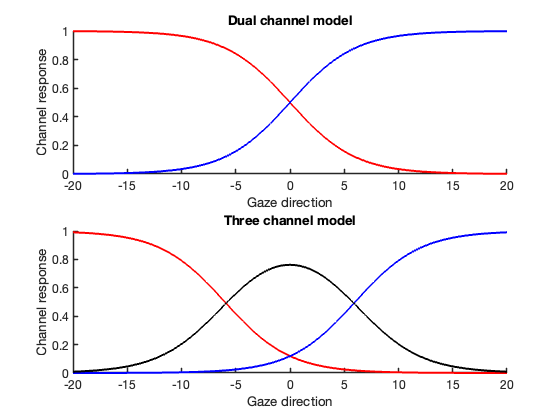

% We compare simulated adaptation according to two function encoding 
% models of gaze perception

% A dual channel model proposes two subpopulations of neurons,
% one increases firing with more leftward gaze and one with more rightward
% gaze

minDir = -20;
maxDir = 20;
nDirs = 1000;
gazeDirs = linspace(minDir, maxDir, nDirs);

slope = 3;
halfMaxDual = 0;
halfMaxThree = 6;


LGchannel = @(dir,halfmax,slope) 1./(1+exp(((dir+halfmax)./slope)));
RGchannel = @(dir,halfmax,slope) 1./(1+exp(-((dir-halfmax)./slope)));
respDC = @(dir,halfmax,slope) (RGchannel(dir,halfmax,slope)-LGchannel(dir,halfmax,slope))...
    ./(RGchannel(dir,halfmax,slope)+LGchannel(dir,halfmax,slope)); 
% the response is the difference in channel activity, normalised by the sum

% a three channel model proposes a third channel coding direct gaze
% this third channel is coded as the difference between the left and right
% and adds more normalisation

DGchannel = @(dir,halfmax,slope) max(1-(LGchannel(dir,halfmax,slope)...
    +RGchannel(dir,halfmax,slope)),0);
respTC = @(dir,halfmax,slope) (RGchannel(dir,halfmax,slope)-LGchannel(dir,halfmax,slope))...
    ./(RGchannel(dir,halfmax,slope)+DGchannel(dir,halfmax,slope)+LGchannel(dir,halfmax,slope)); 

% To explain behaviour we can also add variability to the
% read-out/response, but we can leave that out for the purpose of this
% demonstration

figure;
subplot(2,1,1)
hold on

plot(gazeDirs, LGchannel(gazeDirs,halfMaxDual,slope),'r','LineWidth',2);
plot(gazeDirs, RGchannel(gazeDirs,halfMaxDual,slope),'b','LineWidth',2);
xlabel('Gaze direction')
ylabel('Channel response')
title('Dual channel model')
makeMyPlotPretty

subplot(2,1,2)
hold on

plot(gazeDirs, LGchannel(gazeDirs,halfMaxThree,slope),'r','LineWidth',2);
plot(gazeDirs, RGchannel(gazeDirs,halfMaxThree,slope),'b','LineWidth',2);
plot(gazeDirs, DGchannel(gazeDirs,halfMaxThree,slope),'k','LineWidth',2);
xlabel('Gaze direction')
ylabel('Channel response')
title('Three channel model')
makeMyPlotPretty

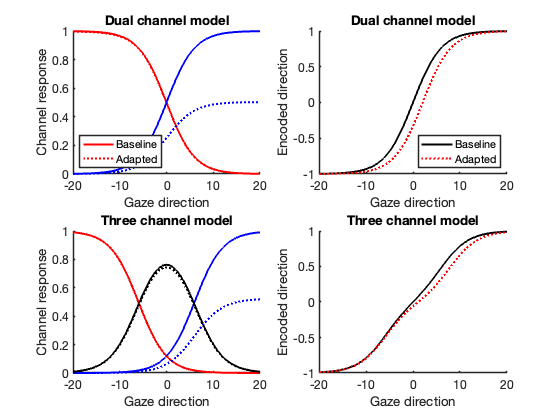

% For adaptation, as above, we assume the response is weakened proportional
% to the response to the adaptor

LGchannelA = @(dir,halfmax,slope,adaptor,alpha) ...
    (1-(alpha.*LGchannel(adaptor,halfmax,slope))).*LGchannel(dir,halfmax,slope);
RGchannelA = @(dir,halfmax,slope,adaptor,alpha) ...
    (1-(alpha.*RGchannel(adaptor,halfmax,slope))).*RGchannel(dir,halfmax,slope);
DGchannelA = @(dir,halfmax,slope,adaptor,alpha) ...
    (1-(alpha.*DGchannel(adaptor,halfmax,slope))).*DGchannel(dir,halfmax,slope);

respDCA = @(dir,halfmax,slope,adaptor,alpha) (RGchannelA(dir,halfmax,slope,adaptor,alpha)...
    -LGchannelA(dir,halfmax,slope,adaptor,alpha))...
    ./(RGchannelA(dir,halfmax,slope,adaptor,alpha)...
    +LGchannelA(dir,halfmax,slope,adaptor,alpha)); 

respTCA = @(dir,halfmax,slope,adaptor,alpha) (RGchannelA(dir,halfmax,slope,adaptor,alpha)-...
    LGchannelA(dir,halfmax,slope,adaptor,alpha))...
    ./(RGchannelA(dir,halfmax,slope,adaptor,alpha)...
    +DGchannelA(dir,halfmax,slope,adaptor,alpha)...
    +LGchannelA(dir,halfmax,slope,adaptor,alpha)); 

% plot the responses pre and post adaptation to direct gaze

adaptor = 15;
adaptStrength = 0.5;

figure;
subplot(2,2,1)
hold on

plot(gazeDirs, LGchannel(gazeDirs,halfMaxDual,slope),'r','LineWidth',2);
plot(gazeDirs, LGchannelA(gazeDirs,halfMaxDual,slope,adaptor,adaptStrength),'r:','LineWidth',2);
plot(gazeDirs, RGchannel(gazeDirs,halfMaxDual,slope),'b','LineWidth',2);
plot(gazeDirs, RGchannelA(gazeDirs,halfMaxDual,slope,adaptor,adaptStrength),'b:','LineWidth',2);
xlabel('Gaze direction')
ylabel('Channel response')
title('Dual channel model')
legend('Baseline','Adapted','location','southwest')
makeMyPlotPretty

subplot(2,2,3)
hold on

plot(gazeDirs, LGchannel(gazeDirs,halfMaxThree,slope),'r','LineWidth',2);
plot(gazeDirs, RGchannel(gazeDirs,halfMaxThree,slope),'b','LineWidth',2);
plot(gazeDirs, DGchannel(gazeDirs,halfMaxThree,slope),'k','LineWidth',2);
plot(gazeDirs, LGchannelA(gazeDirs,halfMaxThree,slope,adaptor,adaptStrength),...
    'r:','LineWidth',2);
plot(gazeDirs, RGchannelA(gazeDirs,halfMaxThree,slope,adaptor,adaptStrength),...
    'b:','LineWidth',2);
plot(gazeDirs, DGchannelA(gazeDirs,halfMaxThree,slope,adaptor,adaptStrength),...
    'k:','LineWidth',2);
xlabel('Gaze direction')
ylabel('Channel response')
title('Three channel model')
makeMyPlotPretty

subplot(2,2,2)
hold on
plot(gazeDirs, respDC(gazeDirs,halfMaxDual,slope),'k','LineWidth',2)
plot(gazeDirs, respDCA(gazeDirs,halfMaxDual,slope,adaptor,adaptStrength),...
    'r:','LineWidth',2)
xlabel('Gaze direction')
ylabel('Encoded direction')
title('Dual channel model')
legend('Baseline','Adapted','location','southeast')
makeMyPlotPretty

subplot(2,2,4)
hold on
plot(gazeDirs, respTC(gazeDirs,halfMaxThree,slope),'k','LineWidth',2)
plot(gazeDirs, respTCA(gazeDirs,halfMaxThree,slope,adaptor,adaptStrength),...
    'r:','LineWidth',2)
xlabel('Gaze direction')
ylabel('Encoded direction')
title('Three channel model')
makeMyPlotPretty

The dual channel model suggests there is no effect of adaptation to direct gaze: both channels are equally adapted and so there is no overall change. The three channel model proposes that there is a repulsion away from direct following adaptation to direct gaze. Experimental evidence showing this repulsion would be evidence in favour of this third channel encoding direct gaze.

**TASK:** Change the adaptor location to see how the models make different predictions about adaptation to other gaze directions.

**TAKE-AWAY 1: **Adaptation gives us a tool to examine the properties of neuronal responses to a stimulus feature, but it is best used in combination with some theory describing the adaptation effect.

### b. External noise

Throughout this course we have added "internal noise" to the observer's perceptual representation of the stimulus. This internal noise means that the exact same external stimulus will provoke different internal responses (different perceptions) on different occasions. 

We can also add external noise. 

This can be demonstrated with my favourite stimulus, the Gabor.

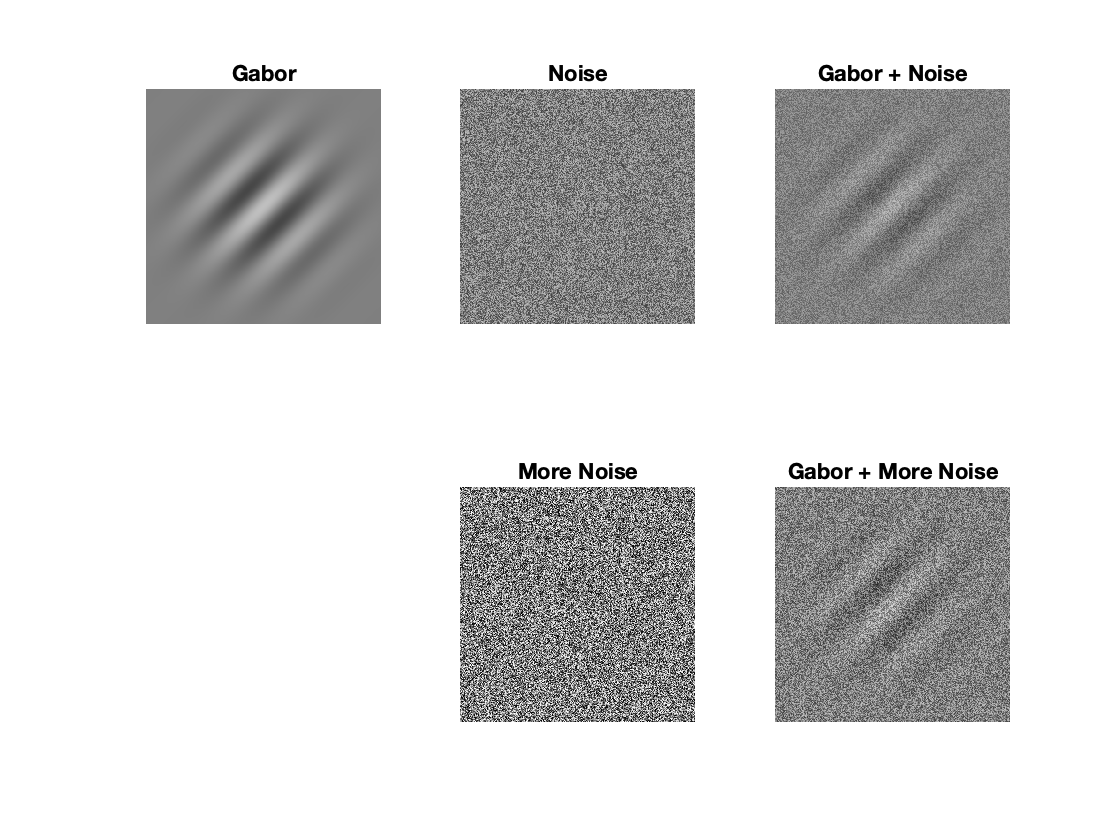

% properties of the Gabor patch - you can play with this
image_size = [501,501]; % pixels

orientation = 45; % in degrees
contrast = 0.5; 
num_cycles = 5; % the number of black to white bits
spatial_frequency = num_cycles/image_size(1);
phase = 1; % this shifts the cycles
sc = image_size(1)/5; % this is for the gaussian envelope

% first we have a 2D map of locations in the image (the x and y
% coordinates)

[x,y] = meshgrid((1:image_size(1))-(image_size(1)+1)/2, ...
    (1:image_size(2))-(image_size(2)+1)/2);
% x and y should go from -250 to 250


% convert angle from deg to rad
orientation = orientation*pi/180;

% apply the sinusoidal filter
u = sin(orientation)*x+cos(orientation)*y;

period = 1/spatial_frequency;
gaborimg = cos(2*pi*(u/period+phase));

% next we apply a 2D gaussian 'envelope' (this blurs the edges)
r = sqrt(x.^2+y.^2); % radius
gaborimg = gaborimg.*normpdf(r,0,sc)/normpdf(0,0,sc);

% normalise
gaborimg = gaborimg - mean(mean(gaborimg));
gaborimg = gaborimg./(max([max(max(gaborimg)),-min(min(gaborimg))]));

% michaelson contrast - there are different types of contrast
scale = 0.5;
gaborimg = (gaborimg*contrast*scale)+(1/2);

% define some "white noise" of the same contrast
% "white noise' draws pixels randomly from a uniform distribution
% ranging from black to white (or in our case, re-scaling to the
% contrast, which is from 0.25 to 0.75)
noise = (rand(image_size)+0.5)./2;

% or a higher contrast
noise2 = rand(image_size);

% the noisy gabor is the gabor + noise (rescaled to black to white)
noisyGabor = ( gaborimg + noise ) ./2;
veryNoisyGabor = ( gaborimg + noise2 ) ./2;

figure;
subplot(2,3,1)
imshow(gaborimg)
title ('Gabor')

subplot(2,3,2)
imshow(noise)
title('Noise')

subplot(2,3,3)
imshow(noisyGabor)
title('Gabor + Noise')

subplot(2,3,5)
imshow(noise2)
title('More Noise')

subplot(2,3,6)
imshow(veryNoisyGabor)
title('Gabor + More Noise')

Adding noise makes it more difficult to see the Gabor signal. Adding different noise on different trials mimicks the variablility of the internal response across multiple presentations.

We can operationalise this in our psychophysical model by suggesting the total noise affecting perception is the sum of the internal + the external noise.

Let's examine what this does in a psychophysical task of orientation discrimination.

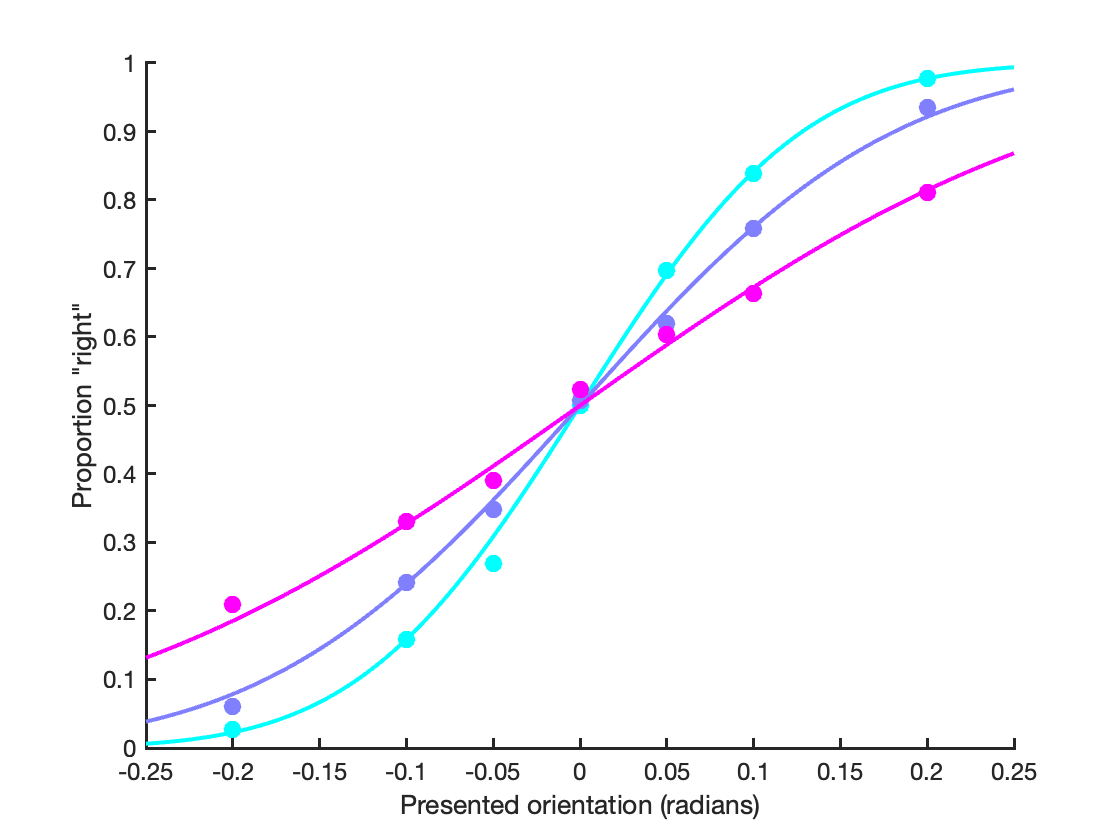

% The orientation varies on each trial:
signal_strengths = [-0.2,-0.1,-0.05,0, 0.05,0.1, 0.2];

nsignals = length(signal_strengths);


% the observer compares the internal value to their representation of
% vertical
criterion = 0;

% the signal is added to internal noise
noise_sd = 0.1;

% plus different levels of external noise
ext_noise_sds = [0,0.1,0.2];
nex = length(ext_noise_sds);

% simulate lots of trials
ntrials = 1000; % per signal strength

proportion_right = nan(nex,nsignals);

% for each external noise level
for ni = 1:nex

    % total noise: sum of variance
    noise_sd_total = sqrt((noise_sd^2) + (ext_noise_sds(ni)^2));


    % samples of internal values which the observer experiences (signal+noise)
    samples = ( randn(ntrials,nsignals)*noise_sd_total ) + signal_strengths;


    proportion_right(ni,:) = mean(samples > criterion,1); % the average  over trials
    
end

% plot
colours = cool(nex);
% for the theoretical psychometric function
xs = linspace(-0.25,0.25,100);
figure;
hold on
for ni = 1:nex
    scatter(signal_strengths,proportion_right(ni,:),80,colours(ni,:),'filled')
    ys = normcdf(xs,criterion,sqrt((noise_sd^2)+(ext_noise_sds(ni)^2)));
    plot(xs,ys,'Color',colours(ni,:),'LineWidth',2)
end
xlabel('Presented orientation (radians)')
ylabel('Proportion "right"')
makeMyPlotPretty

External noise will additionally decrease performance. It is fairly common to add external noise in an experiment for the sole purpose of limiting performance.

We can also use external noise to test cool theories.

Lu and Dosher (1998) used external noise to study how selective attention modulates perception. They used a theoretical model where attention could be used to enhance the signal (like making a light appear brighter), exclude distractors (minimising the impact of irrelevant aspect of the image), or reduce internal noise. Here we will examine how they simulated and tested this theory.

In their experiment the subject is presented with Gabor stimuli on the left and right of fixation, and is asked to report the orientation of both, in sequence. The Gabor stimuli are preceeded and followed by patches of noise (the presentation is so brief that perceptually the noise is added to the Gabors). At the beginning of each trial a cue signals whether the participant should allocate their attention to the left, right, or both sides of fixation. Lu and Dosher measured the threshold constrast of the Gabor at different levels of contrast of external noise, across the different attention conditions.

Lu and Dosher's model is a more complicated psychophysical model. So far, all we have been doing is adding noise to the signal. In their model, there are two types of internal noise, one additive (as we have been doing), and one multiplicative (it increases in variance with increasing stimulus contrast). In this case, the total noise variance is:

total_noise_variance  = external_noise_variance + additive_internal_noise_variance + multiplicative_noise_variance*(perceived_signal + external_noise_variance);

The other complication is with the perceived_signal. Lu and Dosher propose a 'perceptual template' is used to improve perception. This can be thought of as a kind of filtering mechanism. Imagine you know you are going to try to judge the orientation of these noisy Gabors. You can see the noise has very high spatial frequency (pixels next to each other can be very different), but the Gabor itself has quite low spatial frequency (pixels next to each other are very similar), so you want to concentrate on the low spatial frequencies. You can do this by kind of 'defocussing the image' with your eyes. But the model proposes that the brain does this, automatically. It's like the real input is the 'Gabor + More Noise' above, but the brain processes the image such that you perceive the less noisy 'Gabor + Noise' version. I won't go into details about how this is achieved (the maths is complicated). The maths for the perceived signal is very simple.

perceived_signal = beta * gabor_contrast;

beta is a free parameter that upweights (or could even downweight) the signal contrast, meaning the effect of the external noise is reduced.

Sensitivity is simply:

d' = perceived_signal / total_noise_variance

Let's simulate.

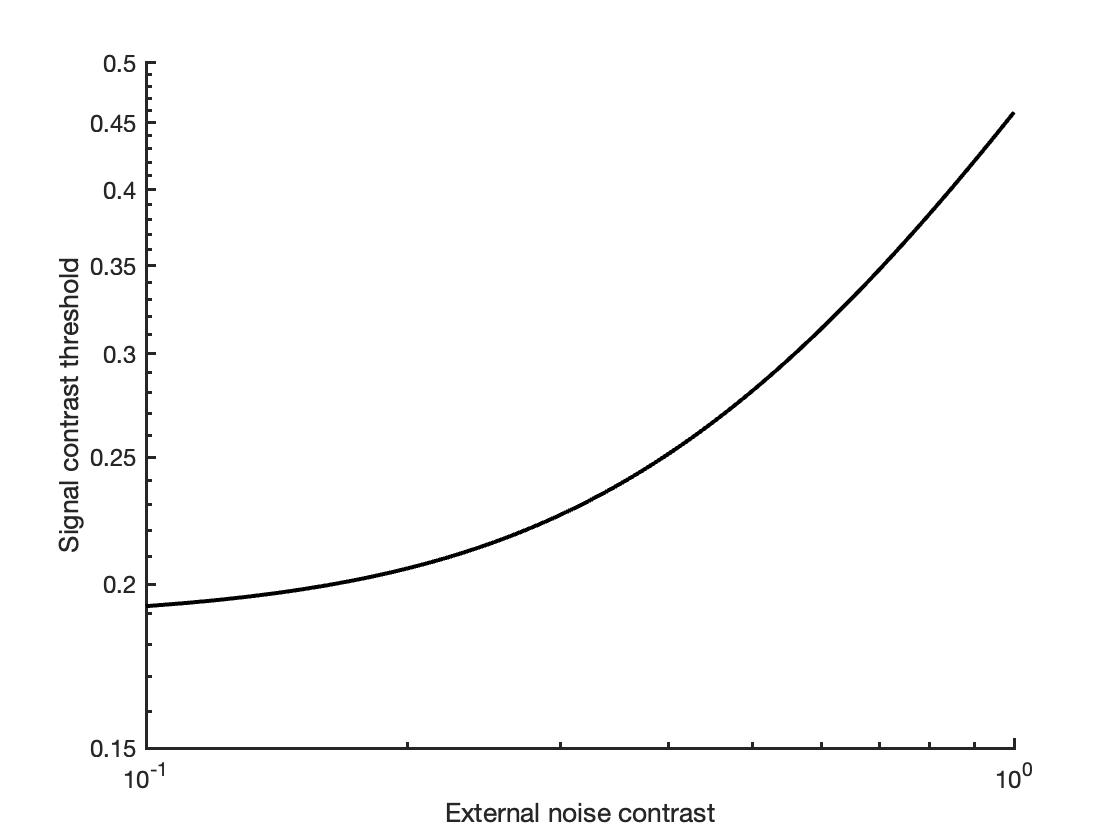

% our key measurement is the signal contrast at a certain threshold level
% This threshold level is
dprime = 1;

% we can fix some key variables
additive_noise_sd = 0.45;
multiplicative_noise_sd = 0.0625;
beta = 2.4;

% external noise contrast is varied
external_noise = linspace(0,1,100);

% the threshold contrast will be
contrast_threshold = sqrt( (((1 + multiplicative_noise_sd^2).*(external_noise.^2)) ...
    + (additive_noise_sd^2)) ./ ...
    ((beta^2) * ((1/(dprime^2)) - multiplicative_noise_sd^2)));

% plot
figure;
hold on

plot(external_noise, contrast_threshold, 'k','LineWidth',2)

ax = gca;
ax.XScale = 'log';
ax.YScale = 'log';
axis([0.1,1,0.15,0.5]) 

xlabel('External noise contrast');
ylabel('Signal contrast threshold');
makeMyPlotPretty

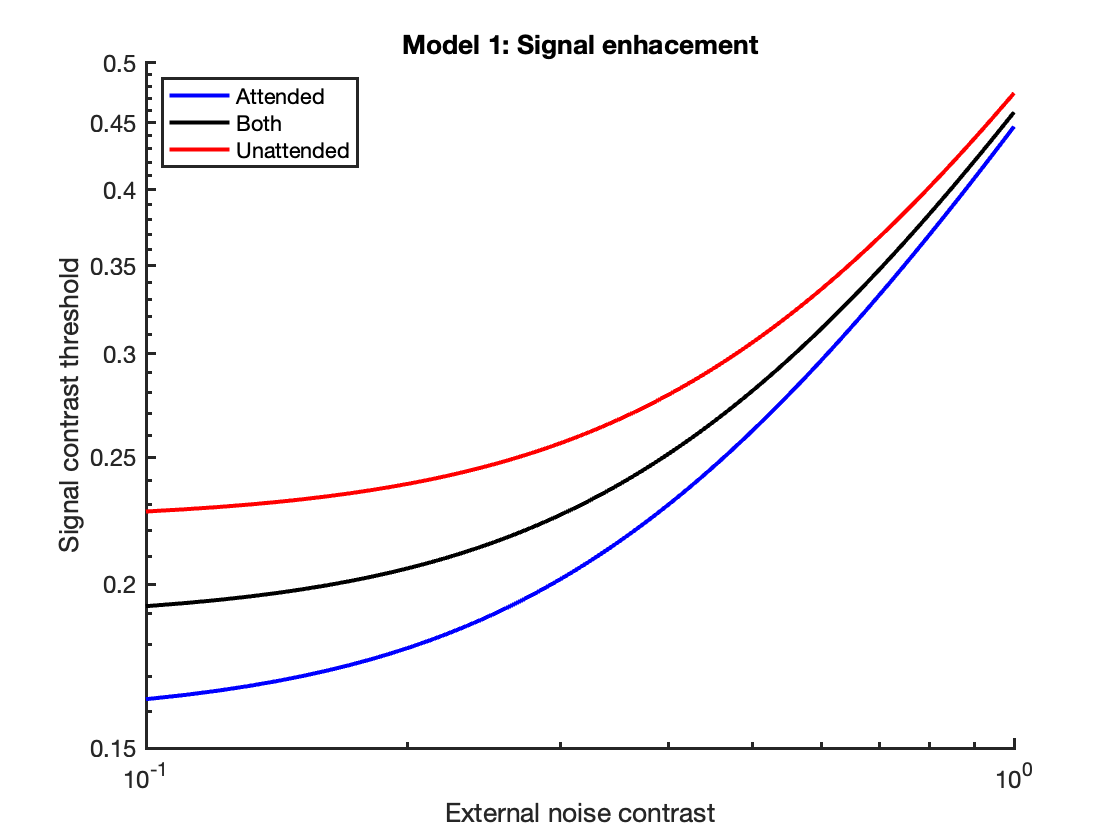

% so what does attention do?

% model 1: attention acts as signal enhancement
% this means that the output of perceptual processes is enhanced
% (both the signal and the external noise)
% this is mathematically equivalent to reducing the additive internal
% noise:

A1_attended = 1.414;
A1_both = 1;
A1_unattended = 0.707;

contrast_threshold_attended_m1 = sqrt( (((1 + multiplicative_noise_sd^2).*(external_noise.^2)) ...
    + ((additive_noise_sd^2) / A1_attended)) ./ ...
    ((beta^2) * ((1/(dprime^2)) - multiplicative_noise_sd^2)));

contrast_threshold_both_m1 = sqrt( (((1 + multiplicative_noise_sd^2).*(external_noise.^2)) ...
    + ((additive_noise_sd^2) / A1_both)) ./ ...
    ((beta^2) * ((1/(dprime^2)) - multiplicative_noise_sd^2)));

contrast_threshold_unattended_m1 = sqrt( (((1 + multiplicative_noise_sd^2).*(external_noise.^2)) ...
    + ((additive_noise_sd^2) / A1_unattended)) ./ ...
    ((beta^2) * ((1/(dprime^2)) - multiplicative_noise_sd^2)));





% plot
figure;
hold on
plot(external_noise, contrast_threshold_attended_m1,'b','LineWidth',2)
plot(external_noise, contrast_threshold_both_m1,'k','LineWidth',2)
plot(external_noise, contrast_threshold_unattended_m1,'r','LineWidth',2)
legend('Attended','Both','Unattended','location','northwest');

ax = gca;
ax.XScale = 'log';
ax.YScale = 'log';
axis([0.1,1,0.15,0.5]) 

xlabel('External noise contrast');
ylabel('Signal contrast threshold');
title('Model 1: Signal enhacement')
makeMyPlotPretty

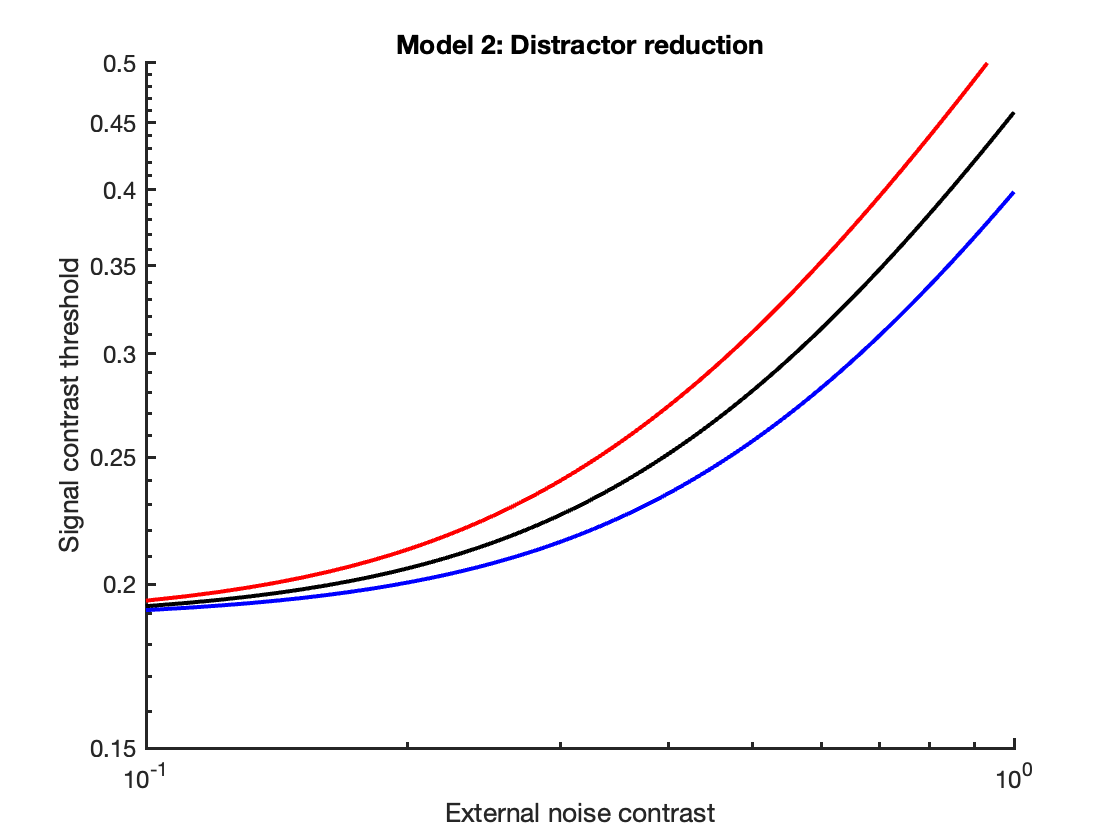


% model 2: attention as as distractor exclusion
% this means that the perceptual filter performs better
% (the signal is enhanced, but not the external noise)
% this is mathematically equivalent to decreasing the external noise:


A2_attended = 0.707;
A2_both = 1;
A2_unattended = 1.414;

contrast_threshold_attended_m2 = sqrt( (((1 + multiplicative_noise_sd^2) ...
    .*(A2_attended.*(external_noise.^2))) ...
    + (additive_noise_sd^2)) ./ ...
    ((beta^2) * ((1/(dprime^2)) - multiplicative_noise_sd^2)));

contrast_threshold_both_m2 = sqrt( (((1 + multiplicative_noise_sd^2) ...
    .*(A2_both.*(external_noise.^2))) ...
    + (additive_noise_sd^2)) ./ ...
    ((beta^2) * ((1/(dprime^2)) - multiplicative_noise_sd^2)));

contrast_threshold_unattended_m2 = sqrt( (((1 + multiplicative_noise_sd^2) ...
    .*(A2_unattended.*(external_noise.^2))) ...
    + (additive_noise_sd^2)) ./ ...
    ((beta^2) * ((1/(dprime^2)) - multiplicative_noise_sd^2)));

figure;
hold on
plot(external_noise, contrast_threshold_attended_m2,'b','LineWidth',2)
plot(external_noise, contrast_threshold_both_m2,'k','LineWidth',2)
plot(external_noise, contrast_threshold_unattended_m2,'r','LineWidth',2)
legend('Attended','Both','Unattended','location','northwest');

ax = gca;
ax.XScale = 'log';
ax.YScale = 'log';
axis([0.1,1,0.15,0.5]) 

xlabel('External noise contrast');
ylabel('Signal contrast threshold');
title('Model 2: Distractor reduction')
makeMyPlotPretty

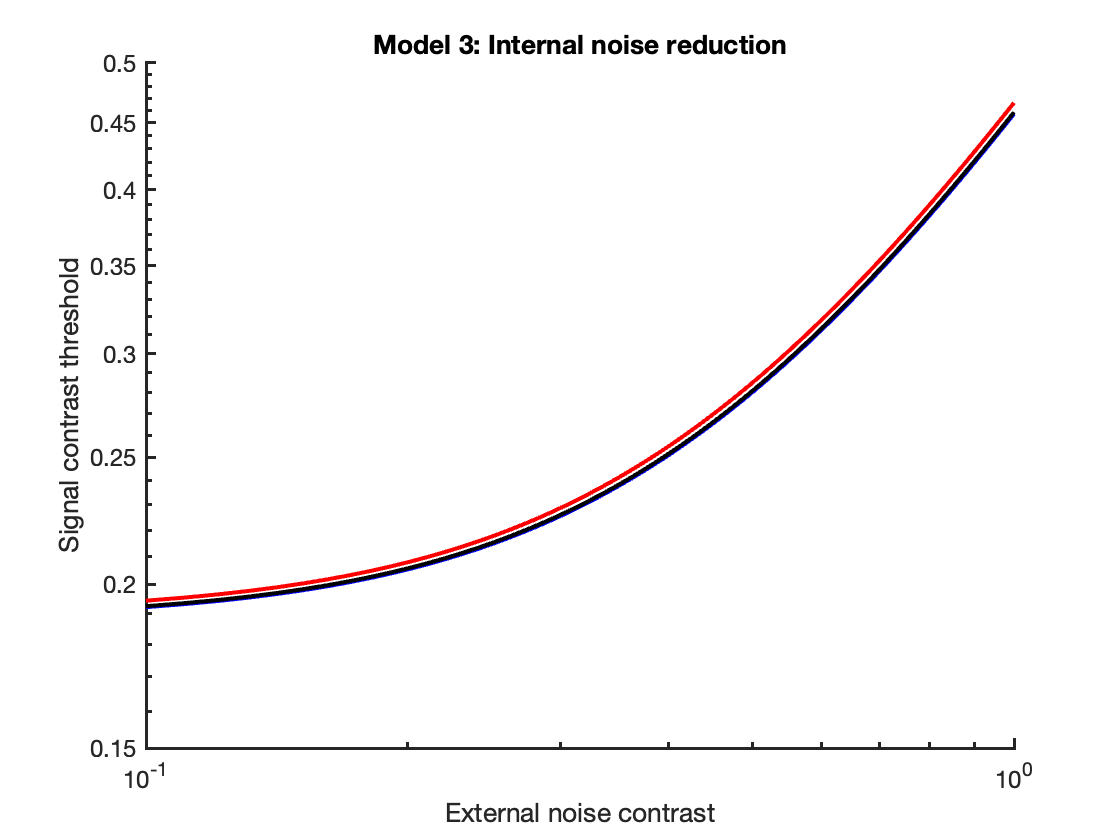


% model 3: attention reduces internal noise
% this is modelled as a reduction in the multiplicative noise


A3_attended = 0.707/4;
A3_both = 1;
A3_unattended = 1.414*4;


contrast_threshold_attended_m3 = sqrt( (((1 + (A3_attended*(multiplicative_noise_sd^2))) ...
    .*(external_noise.^2)) ...
    + (additive_noise_sd^2)) ./ ...
    ((beta^2) * ((1/(dprime^2)) - (A3_attended*(multiplicative_noise_sd^2)))));

contrast_threshold_both_m3 = sqrt( (((1 + (A3_both*(multiplicative_noise_sd^2))) ...
    .*(external_noise.^2)) ...
    + (additive_noise_sd^2)) ./ ...
    ((beta^2) * ((1/(dprime^2)) - (A3_both*(multiplicative_noise_sd^2)))));

contrast_threshold_unattended_m3 = sqrt( (((1 + (A3_unattended*(multiplicative_noise_sd^2))) ...
    .*(external_noise.^2)) ...
    + (additive_noise_sd^2)) ./ ...
    ((beta^2) * ((1/(dprime^2)) - (A3_unattended*(multiplicative_noise_sd^2)))));


figure;
hold on
plot(external_noise, contrast_threshold_attended_m3,'b','LineWidth',2)
plot(external_noise, contrast_threshold_both_m3,'k','LineWidth',2)
plot(external_noise, contrast_threshold_unattended_m3,'r','LineWidth',2)
legend('Attended','Both','Unattended','location','northwest');

ax = gca;
ax.XScale = 'log';
ax.YScale = 'log';
axis([0.1,1,0.15,0.5]) 

xlabel('External noise contrast');
ylabel('Signal contrast threshold');
title('Model 3: Internal noise reduction')
makeMyPlotPretty

Here, the models propose very different functions according to the contrast of external noise. In model 1, attention enhances perception mainly for low levels of external noise contrast. In model 2, attention enhances perception mainly for high levels of external noise contrast. For model 3, attention enhances perception (slightly) across any level of external noise contrast. So for their experiment, the manipulation of external noise contrast was critical for distinguishing these different theories of the mechanism of attention.

Lu and Dosher found their behavioural data aligned with model 1, suggesting attention acts to increase the weight of the external stimulus - both signal + external noise - relative to the internal noise. 

**TAKE-AWAY: **External noise manipulations can be key for understanding perceptual processes (not merely decreasing performance).

**KEY-TAKE-AWAY: **Across the examples so far, a key method has been to simulate a theory of perceptual processes, and design an experiment to test this theory. This is a powerful method for all cognitive science, where a relatively simple behavioural experiment can give important insight into cognitive mechanisms.

### c. Masking

Masking, very broadly, describes when a secondary 'mask' stimulus impacts the perception of a target stimulus. In vision, these stimuli are typically presented at different times (forward masking describes when the mask is presented first, and backward masking, second). Typically, the impact of the mask is measured as a function of the temporal interval between the target and the mask. Traditional masking procedures use a mask that has more 'energy' (e.g. contrast) than the target, with similar perceptual properties, and overlaps in spatial location. In this case, increased time between the target and the mask increases perceptual performance for the task involving the target stimulus. Another technique, meta-contrast masking, involves a mask that does not spatially overlap with the target, and results in a function where performance is high for small durations between target and mask, then decreases for moderate durations (~75 ms) then finally increases again. The duration between target and mask is measured as the stimulus-onset-asyncrony (SOA), and typically the target is presented for a short duration held constant, as opposed to presenting the target for a longer duration with longer SOAs. There's a very nice summary of visual masking on Scholarpedia by Breitmeyer and Ogmen (2007) if you want to read more. Or if you are very interested, Bachmann and Francis (2013) have a fantastic book on the topic (references below).

The timing of the masking effect tells us about the timing of neural processes involved in perception. The very basic theory is that the mask stimulus interrupts the processing of the target, so if a backward mask affects performance for 50 ms it must take 50 ms to process the target stimulus. The theory is actually more complicated, involving reciprocal connections across a heirarchy of functionally specific visual processing regions, the details of which could be an entire course on their own.

Masking was a big hit in the 80's and 90's, not becuase of interest in the timing of neural processes for perception, but because of 'unconscious perception'. Masking was used in studies showing a priming effect, where a masked prime word was shown to modulate response times to a subsequently presented stimulus. A classic study from Marcel (1983) showed masked words naming a colour decreased responses times to name a subsequent colour patch if the masked word was the colour of the patch (and increased response times otherwise). The idea was that some semantic processing occurred though the stimulus was not processed to the point of conscious perception. This idea sparked an obsession with 'subliminal messaging' where an advertisment or campaign could insert masked messages to influence the observer without their knowing it. It was thought that coca-cola could flash an image of their beverage before a film screening so the audience would rush out to buy the beverage. Or, more seriously, that hidden messages could be used to control the population, by the government (the topic of the 2001 movie 'Josie and the Pussycats') or aliens (the topic of the 1988 movie 'They Live').

A key component of studies in unconscious perception is that the masked stimulus is 'unconscious'. If you've been following this course closely, you might find it difficult to formalise what exactly should count as 'unconscious'. 'Unconscious' is something we have to awkardly impose on our theories of perception, since this categorical label is at odds with the continuous nature of perception. We can find more or less liberal definitions. The most liberal would be to ask the observer if they saw the masked stimulus. This would correspond to the stimulus strength at which the observer plases their criterion for reporting seeing the stimulus, which may be more or less conservative depending on the observer. The most conservative approach would be a 2AFC detection task showing 0 sensitivity, meaning that the observer is unable to discriminate the signal from noise alone. 

There is a strategy to get around the problem of what should striclty count as 'unconscious'. This strategy (used in Marcel, 1983, and others) is to show a difference in performance. Specifically, if someone is better at discriminating some aspect of the masked stimulus than they are at detecting the masked stimulus, then we can attribute the superior discrimination performance to unconscious perception. That is, we take a difference in performance as evidence in favour of unconscious perception. This would be logical if unconscious perception were the only way one could predict better performance for discrimination than detection.

For our experiment, we present observers with an Arabic digit, 1, 3, 7, or 9, (or nothing) followed after a variable SOA by a mask, spatially overlapping with the digit, composed of the letters O, X, and T, superimposed (Balsdon & Clifford, 2018). The observer must detect whether the digit was presented, and discriminate whether it corresponds to a quantity greater or less than 5.

First, we will simulate the view from unconscious perception.

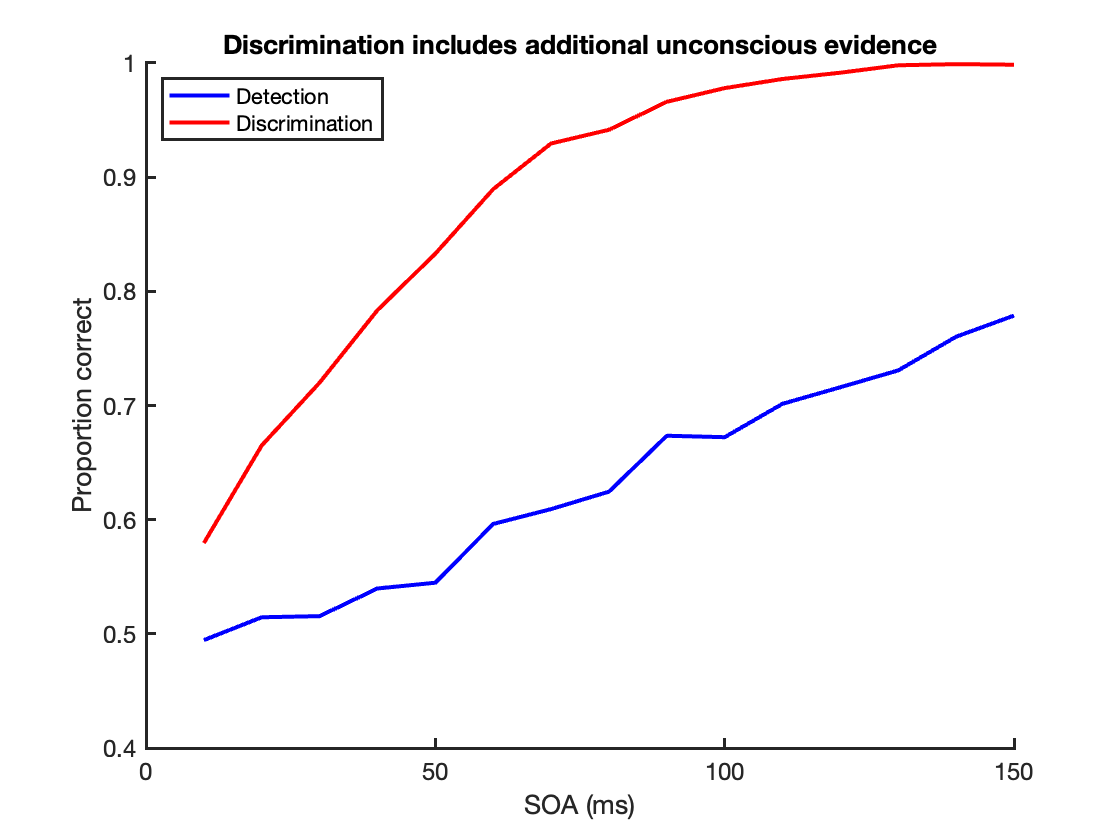

% Here there is conscious evidence used to make the detection response
% Plus some additional unconscious evidence used to make the discrimination
% response

nsoa = 15; % a long experiment, but we're only simulating
nsim = 1000;

soaEv = linspace(0.01,0.15,nsoa);
noise_sd = 0.0354; 
% this number might seem random, but it is not (see next code block)
detection_criterion = 0.0354;

% for our simulation we make 'four' stimulus posibilities
% stimuli less than 5
% stimuli greater than 5
% stimulus absent
% stimulus absent 2 (to make equal probability present/absent)
detection_resps = nan(4,nsoa,nsim); 
discrimination_resps = nan(4,nsoa,nsim);

for soa = 1:nsoa
    
    % conscious evidence
    lessEv = (randn(1,nsim)*noise_sd) + ((soaEv(soa)/2)*-1);
    greaterEv = (randn(1,nsim)*noise_sd) + ((soaEv(soa)/2));
    absentEv1 = (randn(1,nsim)*noise_sd);
    absentEv2 = (randn(1,nsim)*noise_sd);
    
    
    % detection: is the absolute evidence greater than some threshold?
    detection_resps(1,soa,:) = abs(lessEv)>detection_criterion;
    detection_resps(2,soa,:) = abs(greaterEv)>detection_criterion;
    detection_resps(3,soa,:) = abs(absentEv1)>detection_criterion;
    detection_resps(4,soa,:) = abs(absentEv2)>detection_criterion;
    
    % discrimination: add some more evidence (the unconscious stuff)
    
    lessEv = lessEv + (randn(1,nsim)*noise_sd) + ((soaEv(soa)/2)*-1);
    greaterEv = greaterEv + (randn(1,nsim)*noise_sd) + ((soaEv(soa)/2));
    
    % is the evidence greater than 0?
    
    discrimination_resps(1,soa,:) = lessEv>0;
    discrimination_resps(2,soa,:) = greaterEv>0;
    discrimination_resps(3,soa,:) = absentEv1>0;
    discrimination_resps(4,soa,:) = absentEv2>0;
    
end

% detection proportion correct

detection_pcorr = squeeze( ( mean(detection_resps(1,:,:)==1,3) ...
    + mean(detection_resps(2,:,:)==1,3) ...
    + mean(detection_resps(3,:,:)==0,3) ...
    + mean(detection_resps(4,:,:)==0,3) ) ./ 4);

% for discrimination, ignore stimulus absent trials

discrimination_pcorr = squeeze( ( mean(discrimination_resps(1,:,:)==0,3) ...
    + mean(discrimination_resps(2,:,:)==1,3) ) ./ 2);

% plot
figure;
hold on 
plot(soaEv*1000, detection_pcorr, 'b', 'LineWidth', 2);
plot(soaEv*1000, discrimination_pcorr, 'r', 'LineWidth', 2);
legend('Detection', 'Discrimination','location','northwest')
makeMyPlotPretty

xlabel('SOA (ms)')
ylabel('Proportion correct')
title('Discrimination includes additional unconscious evidence')

Here, the proposal is that discrimination is better than detection because there is extra evidence to make the discrimination response. This evidence is unavailable for detection, because detection can only use special conscious evidence.

And the view from conscious perception

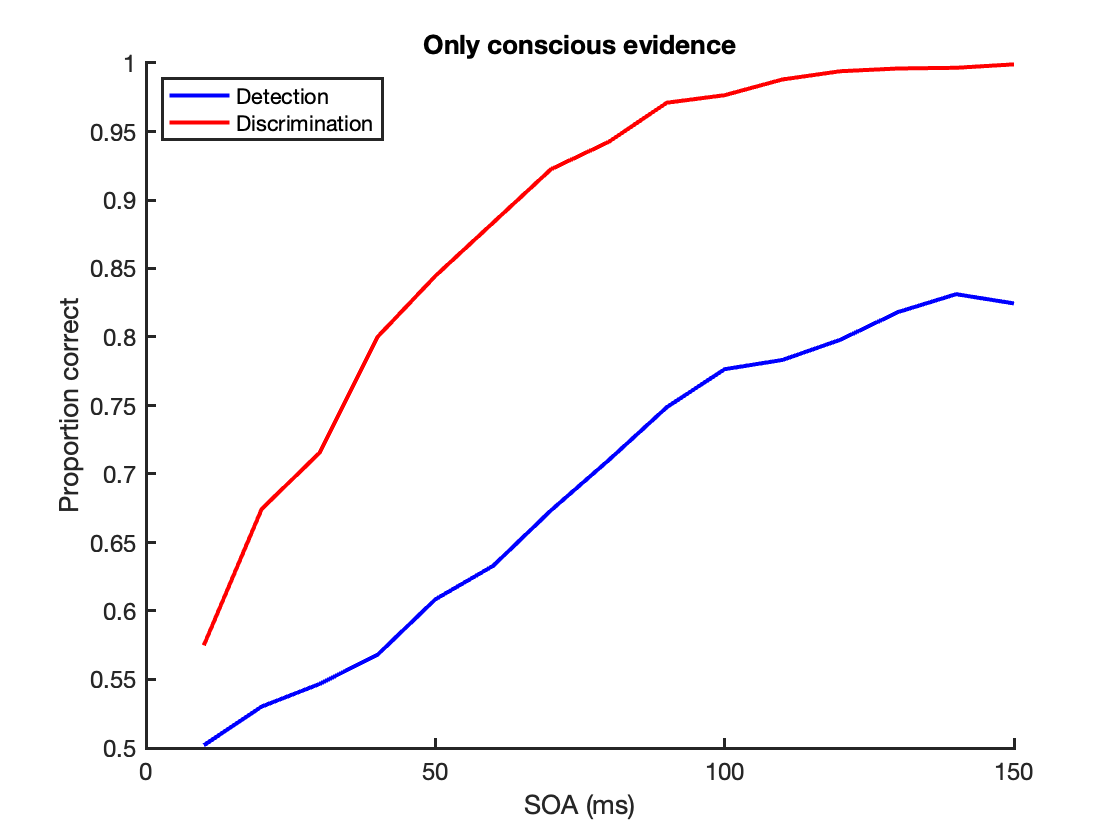

% Here all the evidence is consciously perceived by the observer

% How is it they could have better performance in the discrimination task
% than the detection task?

% Quite simply, the digits are more different from each other than they are
% from nothing (digit absent).

% We can represent this on a single decision axis

% the evidence for digits less than 5 is negative, and greater than 5
% positive

% this evidence increases with increasing SOA
nsoa = 15; % a long experiment, but we're only simulating
nsim = 1000;

soaEv = linspace(0.01,0.15,nsoa);
noise_sd = 0.05;
detection_criterion = 0.05;

% for our simulation we make 'four' stimulus posibilities
% stimuli less than 5
% stimuli greater than 5
% stimulus absent
% stimulus absent 2 (to make equal probability present/absent)
detection_resps = nan(4,nsoa,nsim); 
discrimination_resps = nan(4,nsoa,nsim);

for soa = 1:nsoa
    
    lessEv = (randn(1,nsim)*noise_sd) + (soaEv(soa)*-1);
    greaterEv = (randn(1,nsim)*noise_sd) + (soaEv(soa));
    absentEv1 = (randn(1,nsim)*noise_sd);
    absentEv2 = (randn(1,nsim)*noise_sd);
    
    % detection: is the absolute evidence greater than some threshold?
    detection_resps(1,soa,:) = abs(lessEv)>detection_criterion;
    detection_resps(2,soa,:) = abs(greaterEv)>detection_criterion;
    detection_resps(3,soa,:) = abs(absentEv1)>detection_criterion;
    detection_resps(4,soa,:) = abs(absentEv2)>detection_criterion;
    
    % discrimination: is the evidence greater than 0?
    discrimination_resps(1,soa,:) = lessEv>0;
    discrimination_resps(2,soa,:) = greaterEv>0;
    discrimination_resps(3,soa,:) = absentEv1>0;
    discrimination_resps(4,soa,:) = absentEv2>0;
    
end

% detection proportion correct

detection_pcorr = squeeze( ( mean(detection_resps(1,:,:)==1,3) ...
    + mean(detection_resps(2,:,:)==1,3) ...
    + mean(detection_resps(3,:,:)==0,3) ...
    + mean(detection_resps(4,:,:)==0,3) ) ./ 4);

% for discrimination, ignore stimulus absent trials

discrimination_pcorr = squeeze( ( mean(discrimination_resps(1,:,:)==0,3) ...
    + mean(discrimination_resps(2,:,:)==1,3) ) ./ 2);

% plot
figure;
hold on 
plot(soaEv*1000, detection_pcorr, 'b', 'LineWidth', 2);
plot(soaEv*1000, discrimination_pcorr, 'r', 'LineWidth', 2);
legend('Detection', 'Discrimination','location','northwest')
makeMyPlotPretty

xlabel('SOA (ms)')
ylabel('Proportion correct')
title('Only conscious evidence')

Under this model, discrimination is better than detection because the stimuli are more different from each other than they are from nothing. One doesn't need unconscious evidence to perform better in a discrimination task than a detection task.

There is also a second limit on detection proportion correct: a biased criterion.

**TASK: **change the detection_criterion in the code above to see what happens to detection proportion correct.

This would be less problematic if we examined sensitivity (d') instead of proportion correct.

**KEY-TAKE-AWAY: **Just because your data confirms your theoretical prediction does not mean your theoretical prediction is correct. Be careful to examine potential 'null' models to properly test (aim to falsify) your theory.

### Functions

function makeMyPlotPretty()

ax = gca;
ax.FontSize = 12;
ax.LineWidth=1.5;

end

#### References

Addams, R. (1834). An account of a peculiar optical phenomenon seen after having looked at a moving body. *London and Edinburgh Philosophical Magazine and Journal of Science*, 5: 373-374

Bachmann, T., & Francis, G. (2013). *Visual masking: Studying perception, attention, and consciousness*. Academic Press.

Balsdon, T., & Clifford, C. W. (2018). Visual processing: Conscious until proven otherwise. *Royal Society Open Science*, *5*(1), 171783.

Breitmeyer, B. G., & Ogmen, H. (2007). Visual masking. *Scholarpedia*, *2*(7), 3330.

Clifford, C. W., & Palmer, C. J. (2018). Adaptation to the direction of others’ gaze: A review. *Frontiers in psychology*, *9*, 2165.

Frisby, J. (1979). Seeing: Illusion, brain, and mind: Oxford University Press.

Gepshtein, S., Lesmes, L. A., & Albright, T. D. (2013). Sensory adaptation as optimal resource allocation. *Proceedings of the National Academy of Sciences*, *110*(11), 4368-4373.

Jazayeri, M., & Movshon, J. A. (2006). Optimal representation of sensory information by neural populations. *Nature neuroscience*, *9*(5), 690-696.

Kohn, A., & Movshon, J. A. (2003). Neuronal adaptation to visual motion in area MT of the macaque. *Neuron*, *39*(4), 681-691.

Lu, Z. L., & Dosher, B. A. (1998). External noise distinguishes attention mechanisms. *Vision research*, *38*(9), 1183-1198.

Marcel, A. J. (1983). Conscious and unconscious perception: Experiments on visual masking and word recognition. *Cognitive psychology*, *15*(2), 197-237.

Palmer, C. J., & Clifford, C. W. (2017). Functional mechanisms encoding others' direction of gaze in the human nervous system. *Journal of Cognitive Neuroscience*, *29*(10), 1725-1738.

Perrett, D. I., Smith, P. A. J., Potter, D. D., Mistlin, A. J., Head, A. S., Milner, A. D., & Jeeves, M. A. (1985). Visual cells in the temporal cortex sensitive to face view and gaze direction. *Proceedings of the Royal society of London. Series B. Biological sciences*, *223*(1232), 293-317.

Senju, A., & Johnson, M. H. (2009). The eye contact effect: mechanisms and development. *Trends in cognitive sciences*, *13*(3), 127-134.

Seung, H. S., & Sompolinsky, H. (1993). Simple models for reading neuronal population codes. *Proceedings of the national academy of sciences*, *90*(22), 10749-10753.

Solomon, S. G., & Kohn, A. (2014). Moving sensory adaptation beyond suppressive effects in single neurons. *Current biology*, *24*(20), R1012-R1022.